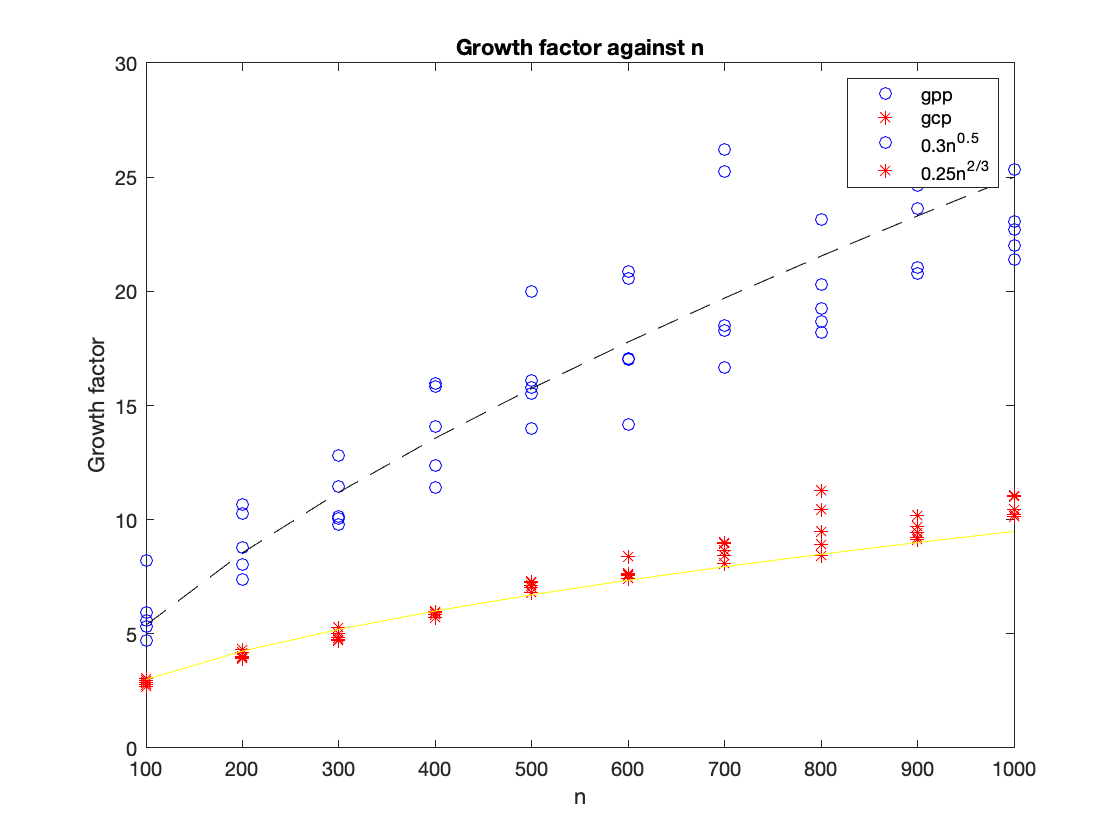

clear all
close all

n = [100:100:1000]';

N = length(n);

gcp = zeros(N,5);
gpp = zeros(N,5);
for i = 1:N
    for j = 1:5
        A = rand(n(i));
        [LU,p,q,gf,L,U]= lucp(A);
        gcp(i,j) = gf;
        [L,U,P,g] = lupp(A);
        gpp(i,j) = g;
    end
end

for k = 1:5
    plot(n,gpp(:,k),'bo');
    hold on
    plot(n,gcp(:,k),'r*');
    hold on
end

plot(n,0.3*(n.^0.5),'y')
hold on
plot(n,0.25*(n.^(2/3)),'k--')
legend('gpp','gcp','0.3n^0^.^5','0.25n^2^/^3')
title('Growth factor against n')
xlabel('n'); ylabel('Growth factor')